# Integrity Analysis

Configuration and Data Load

clc; clear; close all;

addpath('./utils');
addpath('./config');

run('config');


Plotting variables definition:

%% Global plotting style
fontAxis   = 15;
fontTitle  = 17;
fontLegend = 13;
lineMain   = 2.0;
gridColor  = [0.82 0.82 0.82];
figSizeMap     = [18.0 12.5];
figSizeWide    = [18.5 11.5];
figSizeStacked = [17.0 15.0];


load(rxLLAFile, 'latPoly', 'lonPoly', 'altPoly');

% Define a colormap from light to dark for DOP importance.
% (lighter = component DOPs, darker = composite/global)
colors = [
    0.9 0.9 0.0;   % yellow  = HDOP (less global)
    0.0 0.7 0.0;   % green   = VDOP
    0.0 0.5 1.0;   % blue    = TDOP
    1.0 0.5 0.0;   % orange  = PDOP (combined)
    0.8 0.0 0.0];  % red     = GDOP (most global)

## Galileo

### Loading simulation data

load(rxENUFile, 'receiverPositions', 'samplingRate');
load(galLoSFile, ...
    'visibilityMap', ...
    'svPositionsECEF', ...
    'svPositions_ENU', ...
    'svPositions_ECEF', ...
    'svPositions_TX_ECEF', ...
    'svPositions_Sagnac_ECEF', ...
    'trueRange', ...
    'measPseudorange', ...
    'signalTravelTime', ...
    'earthRotation', ...
    'Fs_gnss');

load(galSimFile, ...
    'estENU', ...
    'estError', ...
    'TsGalileo_pos');

sigma = 4.6     % Standard deviation in pseudorange measurements. (in meters)

sigma = 4.6000

### Protection Level Computation

The measured pseudorange can be expressed as:

        
$$$$\rho^{(k)}(t)=r^{k}(t,t-\tau)+c\cdot\left[dt(t)-dt^{(k)}\right]+I^{(k)}+T^{(k)}+\epsilon^{(k)}$$$$


Following Newton-Rapson method the quadratic set of equations can be linearized. It is defined a known pseudorange for a given location $\mathbf{x_0}}$:

        
$$\rho_{0}^{(k)}(t)=\left|\left|\mathbf{x^{(k)}}-\mathbf{x_0}\right|\right|+b_0+\epsilon^{(k)}$$


Therefore, and knowing that $\left|\left|\mathbf{x^{(k)}}-\mathbf{x}\right|\right|=\left|\left|\mathbf{x^{(k)}}-\mathbf{x_0-\delta\mathbf{x}}\right|\right|$:

        
$$\delta\rho^{(k)}=\rho_c^{(k)}-\rho_0^{(k)}=\left|\left|\mathbf{x^{(k)}}-\mathbf{x_0}-\delta\mathbf{x}\right|\right|-\left|\left|\mathbf{x^{(k)}}-\mathbf{x_0}\right|\right|$$


Finally, aproximation to the first order of Taylor the expression:


$$\left|\left|\mathbf{x^{(k)}}-\mathbf{x_0}-\delta\mathbf{x}\right|\right|=
\sqrt{
	\left(
		x^{(k)}-x_0^{(k)})-\delta x
	\right)^2
	+
	\left(
		y^{(k)}-y_0^{(k)})-\delta y
	\right)^2
	+
	\left(
		z^{(k)}-z_0^{(k)})-\delta z
	\right)^2
	
}
$$



$$\left|\left|\mathbf{x^{(k)}}-\mathbf{x_0}-\delta\mathbf{x}\right|\right|
\approx
\left|\left|
	\mathbf{x}^{(k)}-\mathbf{x}_0
\right|\right|
-
\frac{
		\left(
			\mathbf{x}^{(k)}-\mathbf{x}_0
		\right)
} {
	\left|\left|
		\mathbf{x}^{(k)}-\mathbf{x}_0
	\right|\right|
} \cdot \delta \mathbf{x}
= 
\left|\left|
	\mathbf{x}^{(k)}-\mathbf{x}_0
\right|\right|-\mathbf{u}^{(k)}$$


As a result:


$$\underset{\delta\mathbf{\rho}}{
\left[
\begin{array}{c}
\delta\rho^{(1)} \\
\delta\rho^{(2)} \\
\vdots \\
\delta\rho^{(K)}
\end{array}
\right]
}
=
\underset{\mathbf{G}}{
\left[
\begin{array}{cc}
-\mathbf{u}^{(1)T} & 1 \\
-\mathbf{u}^{(2)T} & 1 \\
\vdots & \vdots \\
-\mathbf{u}^{(K)T} & 1
\end{array}
\right]
}
\left[
\begin{array}{c}
\delta\mathbf{x} \\
\delta b
\end{array}
\right]
+
\mathbf{\varepsilon}_p$$


The solution is solved by Least Squares.

        
$$\hat{\mathbf{x}} = (\mathbf{A}^{T}\mathbf{A})^{-1}\mathbf{A}^{T}\mathbf{b}
$$


% Satellite positions and receiver trajectory
% Dimensions: [Ntx x 3 x Nep]
[Ntx, ~, Nep] = size(svPositions_Sagnac_ECEF);
Nuser   = size(receiverPositions,1);
idxRx   = round((1:Nep)' * samplingRate * TsGalileo_pos); % idx = k * Fs_user / Fs_gnss
idxRx   = min(max(idxRx,1), Nuser);

trueENU = receiverPositions(idxRx, :);       % True ENU for each GNSS epoch

% Extract ECEF coordinates: [Ntx x Nep]
x = reshape(svPositions_Sagnac_ECEF(:,1,:), Ntx, Nep);
y = reshape(svPositions_Sagnac_ECEF(:,2,:), Ntx, Nep);
z = reshape(svPositions_Sagnac_ECEF(:,3,:), Ntx, Nep);

% Convert ECEF to ENU
[e, n, u] = ecef2enu(x, y, z, ...
                     refLat, refLon, h0, ellipsoid);

% Reconstruct [Ntx x 3 x Nep]
svs = cat(2, ...
    reshape(e, Ntx, 1, Nep), ...
    reshape(n, Ntx, 1, Nep), ...
    reshape(u, Ntx, 1, Nep));

nEpochs = size(svs, 3);
minElevDeg = 10;  % Elevation mask [deg]

% Compute DOPs
dop = computeDOPsFromENU(svs, trueENU, visibilityMap, trueRange);

% Extract values
HDOP = dop.HDOP; VDOP = dop.VDOP; TDOP = dop.TDOP; PDOP = dop.PDOP; GDOP = dop.GDOP;
HPL = sigma*HDOP; VPL = sigma*VDOP; PPL = sigma*PDOP;

### Results plot

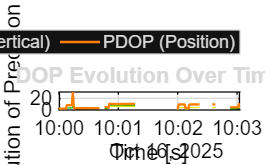

% Create figure
startTime; 
tSec = startTime + seconds((0:Nep-1)'*TsGalileo_pos);
f_dop = createThesisFigure(figSizeWide, 'Name', 'Dilution of Precision');
hold on; grid on; box on;

% Plot with thicker lines for more "important" DOPs
plot(tSec, HDOP, 'Color', colors(1,:), 'LineWidth', 1.0);
plot(tSec, VDOP, 'Color', colors(2,:), 'LineWidth', 1.0);
plot(tSec, PDOP, 'Color', colors(4,:), 'LineWidth', 1.8);

xlim([min(tSec) max(tSec)]);

% Labels and legend
xlabel('Time [s]');
ylabel('Dilution of Precision');
title('DOP Evolution Over Time');

lgd = legend({'HDOP (Horizontal)', 'VDOP (Vertical)', ...
              'PDOP (Position)'}, ...
              'Location','northoutside', ...
              'Orientation','horizontal', ...
              'NumColumns', 3);

% Make it pretty
set(gca, 'FontSize', fontAxis, ...
         'LineWidth', 1.0, ...
         'Color', 'w', ...
         'GridColor', gridColor, ...
         'GridAlpha', 0.8, ...
         'XColor', 'k', ...
         'YColor', 'k');

hold off;

## RAIM detection

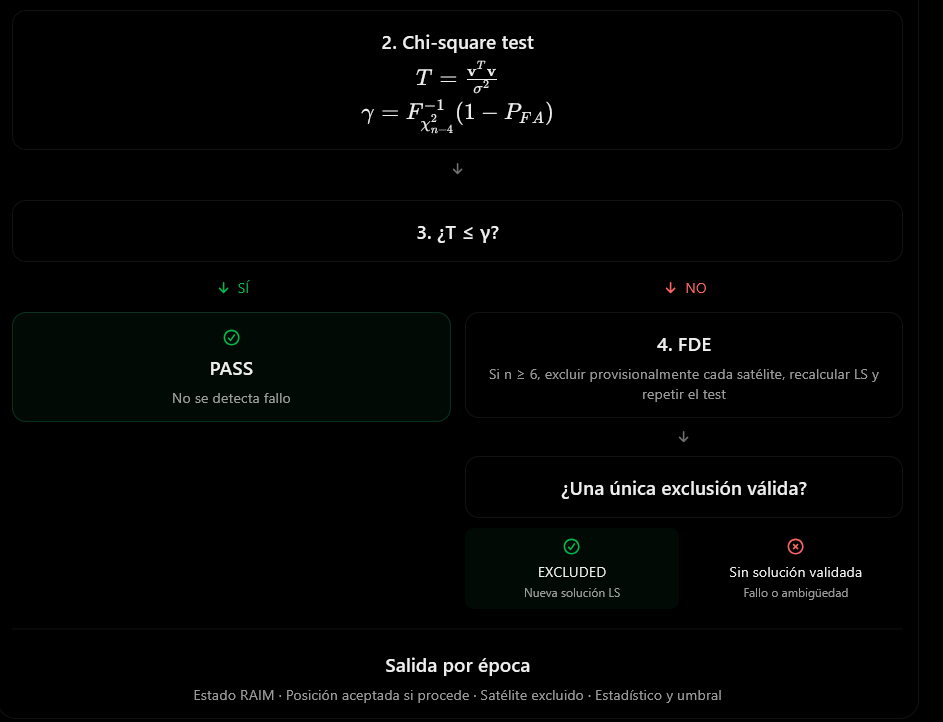

Pfa = 1e-3;
nEpochs = size(svs,3);

Tstat = nan(nEpochs,1);
threshold = nan(nEpochs,1);
Tinitial = nan(nEpochs,1);

raimStatus = strings(nEpochs,1);
excludedSat = nan(nEpochs,1);
raimEstENU = nan(nEpochs,3);

Hfault = nan(nEpochs,1);
Vfault = nan(nEpochs,1);

for k = 1:nEpochs

    % Visible satellite indices
    idx = find(visibilityMap(:,k) == 1);

    % Satellite positions and pseudoranges
    sat = svs(idx,:,k);
    pr = measPseudorange(idx,k);

    % Initial receiver position estimate
    x0 = estENU(k,:).';

    % RAIM Detection and Exclusion
    result = raimFdeEpoch( ...
        sat, pr, idx, x0, sigma, Pfa);
    
    if result.status == "PASS" || result.status == "EXCLUDED"
    
        % Satellites used in the accepted LS solution
        usedIdx = idx;
    
        if result.status == "EXCLUDED"
            usedIdx(usedIdx == result.excludedSat) = [];
        end
    
        % Critical fault bounds
        bounds = raimFaultBounds( ...
            svs(usedIdx,:,k), ...
            result.posENU, ...
            sigma, Pfa, 1e-3);
    
        if bounds.valid
            Hfault(k) = bounds.Hfault;
            Vfault(k) = bounds.Vfault;
        end
    end


    % Store results
    Tstat(k) = result.T;
    Tinitial(k) = result.Tinitial;
    threshold(k) = result.threshold;

    raimStatus(k) = result.status;
    excludedSat(k) = result.excludedSat;
    raimEstENU(k,:) = result.posENU;
end


### Protection Level computing


for k = 1:nEpochs

    % Only the global RAIM PASS branch is covered
    % by the current integrity-risk derivation.
    if raimStatus(k) ~= "PASS"
        continue;
    end

    idx = visibilityMap(:,k) == 1;

    pl = raimProtectionLevel( ...
        svs(idx,:,k), ...
        raimEstENU(k,:), ...
        sigma, Pfa, Pmd, alphaH, alphaV);

    if ~pl.valid
        continue;
    end

    HPL(k) = pl.HPL;
    VPL(k) = pl.VPL;

    Hnom(k) = pl.Hnom;
    Vnom(k) = pl.Vnom;

    Hfault(k) = pl.Hfault;
    Vfault(k) = pl.Vfault;
end

Unrecognized function or variable 'Pmd'.

#### Protection Level Plot

figure;

subplot(2,1,1);
plot(HPL,'LineWidth',1.2); hold on;
plot(Hnom,'--','LineWidth',1);
grid on;
ylabel('Horizontal error bound [m]');
legend('HPL','Nominal contribution');
title('Galileo RAIM - Horizontal Protection Level');

subplot(2,1,2);
plot(VPL,'LineWidth',1.2); hold on;
plot(Vnom,'--','LineWidth',1);
grid on;
xlabel('Galileo epoch');
ylabel('Vertical error bound [m]');
legend('VPL','Nominal contribution');

### Ground truth comparation and real error extraction

posErrENU = estENU - trueENU;              % [184 x 3] ENU errors
posErrAbs = vecnorm(posErrENU,2,2);        % 3D Euclidean error
h_err     = vecnorm(posErrENU(:,1:2),2,2); % Horizontal error
v_err     = abs(posErrENU(:,3));           % Signed vertical error

f_pose = createThesisFigure(figSizeStacked, 'Name', 'Positioning errors per axis');
subplot(3,1,1); plot(tSec, h_err, 'LineWidth',1.2); grid on; ylabel('Horizontal_{error} [m]'); title('Horizontal error'); xlim([min(tSec) max(tSec)]);
subplot(3,1,2); plot(tSec, v_err, 'LineWidth',1.2); grid on; ylabel('N_{error} [m]'); title('Vertical error'); xlim([min(tSec) max(tSec)]);
subplot(3,1,3); plot(tSec, posErrAbs, 'LineWidth',1.2); grid on; ylabel('U_{error} [m]'); title('Total Error'); xlim([min(tSec) max(tSec)]);
xlabel('Time [s]');


## USED FUNCTIONS



function out = raimFdeEpoch(satENU, pr, satIDs, x0, sigma, Pfa)
% RAIM Fault Detection and Exclusion (FDE)
%
% Inputs:
%   satENU : [Nsat x 3] Satellite positions in ENU [m]
%   pr     : [Nsat x 1] Corrected pseudoranges [m]
%   satIDs : [Nsat x 1] Original satellite indices
%   x0     : [3 x 1] Initial receiver position ENU [m]
%   sigma  : Common pseudorange standard deviation [m]
%   Pfa    : False alarm probability per global test
%
% Outputs:
%   status       : PASS / EXCLUDED / FAULT_DETECTED /
%                  AMBIGUOUS / UNAVAILABLE
%   excludedSat  : Original index of excluded satellite
%   posENU       : Validated position estimate
%   clockBias_m  : Estimated receiver clock bias [m]
%   T            : Final chi-square statistic
%   threshold    : Final detection threshold
%   Tinitial     : Original chi-square statistic
%   residuals    : Final post-fit residuals
%
% Assumptions:
%   - Independent Gaussian measurement errors
%   - Common sigma
%   - At most one faulty satellite for FDE

    pr = pr(:);
    satIDs = satIDs(:);
    x0 = x0(:);
    n = numel(pr);

    assert(size(satENU,1) == n && size(satENU,2) == 3);
    assert(numel(satIDs) == n && numel(x0) == 3);
    assert(isfinite(sigma) && sigma > 0);
    assert(Pfa > 0 && Pfa < 1);

    out = struct( ...
        'status', "UNAVAILABLE", ...
        'excludedSat', NaN, ...
        'candidateSats', [], ...
        'posENU', nan(1,3), ...
        'clockBias_m', NaN, ...
        'residuals', [], ...
        'T', NaN, ...
        'threshold', NaN, ...
        'Tinitial', NaN, ...
        'nUsed', 0);

    % At least 5 satellites for RAIM detection
    if n < 5
        return;
    end

    % Step 1: Global RAIM test
    fit = solveLsTest(satENU, pr, x0, sigma, Pfa);

    if ~fit.valid
        return;
    end

    out.Tinitial = fit.T;
    out.T = fit.T;
    out.threshold = fit.threshold;

    % No fault detected
    if fit.T <= fit.threshold
        out.status = "PASS";
        out.posENU = fit.x(1:3).';
        out.clockBias_m = fit.x(4);
        out.residuals = fit.residuals;
        out.nUsed = n;
        return;
    end

    % Fault detected
    out.status = "FAULT_DETECTED";

    % At least 6 satellites for detection + exclusion
    if n < 6
        return;
    end

    % Step 2: Leave-one-out fault exclusion
    candidates = [];
    candidateFits = cell(n,1);

    for i = 1:n

        keep = true(n,1);
        keep(i) = false;

        % Recompute LS excluding satellite i
        candidate = solveLsTest( ...
            satENU(keep,:), pr(keep), ...
            x0, sigma, Pfa);

        if ~candidate.valid
            continue;
        end

        % Test consistency of remaining satellites
        if candidate.T <= candidate.threshold
            candidates(end+1) = i;
            candidateFits{i} = candidate;
        end
    end

    out.candidateSats = satIDs(candidates);

    % Step 3: Accept only an unambiguous exclusion
    if numel(candidates) > 1
        out.status = "AMBIGUOUS";
        return;
    elseif isempty(candidates)
        return;
    end

    % Exactly one candidate passes
    i = candidates(1);
    best = candidateFits{i};

    out.status = "EXCLUDED";
    out.excludedSat = satIDs(i);
    out.posENU = best.x(1:3).';
    out.clockBias_m = best.x(4);
    out.residuals = best.residuals;
    out.T = best.T;
    out.threshold = best.threshold;
    out.nUsed = n-1;
end


function fit = solveLsTest(satENU, pr, x0, sigma, Pfa)
% Iterative LS with chi-square residual consistency test

    n = numel(pr);

    fit = struct('valid',false, ...
                 'x',nan(4,1), ...
                 'residuals',[], ...
                 'T',NaN, ...
                 'threshold',NaN);

    if n < 5 || any(~isfinite(satENU(:))) || ...
            any(~isfinite(pr)) || any(~isfinite(x0))
        return;
    end

    % Initial receiver clock bias estimate
    r0 = vecnorm(satENU - x0.', 2, 2);
    x = [x0; median(pr-r0)];

    converged = false;

    for iter = 1:20

        d = satENU - x(1:3).';
        r = vecnorm(d,2,2);

        if any(r <= 0)
            return;
        end

        % Geometry matrix
        G = [-d./r, ones(n,1)];

        % Check geometry conditioning using QR
        [~,Rg] = qr(G,0);
        if rcond(Rg) < 1e-10
            return;
        end

        % Gauss-Newton LS update
        residual = pr - (r+x(4));
        dx = G \ residual;

        x = x + dx;

        if norm(dx) < 1e-5
            converged = true;
            break;
        end
    end

    if ~converged
        return;
    end

    % Final post-fit residuals
    r = vecnorm(satENU - x(1:3).',2,2);
    residual = pr - (r+x(4));

    % Chi-square test
    T = (residual.'*residual)/sigma^2;
    gamma = chi2inv(1-Pfa,n-4);

    fit.valid = true;
    fit.x = x;
    fit.residuals = residual;
    fit.T = T;
    fit.threshold = gamma;
end


function out = raimFaultBounds(satENU, posENU, sigma, Pfa, Pmd)
% RAIM fault-induced horizontal and vertical bounds
% Single-satellite fault hypothesis, common sigma
%
% satENU : [Nsat x 3] satellite positions in ENU
% posENU : [1 x 3] estimated receiver position in ENU
% sigma  : pseudorange standard deviation [m]
% Pfa    : false alarm probability per global test
% Pmd    : target missed detection probability

    n = size(satENU,1);

    out = struct('valid',false, ...
                 'slopeH',[], 'slopeV',[], ...
                 'biasCritical',[], ...
                 'lambdaB',NaN, 'pbiasB',NaN, ...
                 'Hfault',NaN, 'Vfault',NaN);

    if n < 5
        return;
    end

    assert(sigma > 0);
    assert(Pfa > 0 && Pfa < 1);
    assert(Pmd > 0 && Pmd < 1-Pfa);

    % 1. Geometry matrix
    los = satENU - posENU(:).';
    rho = vecnorm(los,2,2);
    u = los ./ rho;

    G = [-u, ones(n,1)];

    % 2. Least-squares projection matrices
    [Q,R] = qr(G,0);

    if rcond(R) < 1e-10
        return;
    end

    A = R \ Q.';

    % Diagonal of B = G*A = Q*Q'
    Bii = sum(Q.^2,2);
    parityGain = sqrt(max(0,1-Bii));

    if any(parityGain < 1e-8)
        out.Hfault = Inf;
        out.Vfault = Inf;
        return;
    end

    % 3. SLOPE for each satellite
    slopeH = hypot(A(1,:),A(2,:)) ./ parityGain.';
    slopeV = abs(A(3,:)) ./ parityGain.';

    % 4. Central chi-square detection threshold
    dof = n-4;
    gamma = chi2inv(1-Pfa,dof);

    % 5. Noncentrality parameter for target Pmd
    f = @(lambda) ncx2cdf(gamma,dof,lambda)-Pmd;

    upper = 1;
    while f(upper) > 0
        upper = 2*upper;
    end

    lambdaB = fzero(f,[0 upper]);

    % 6. Critical bias in parity space
    pbiasB = sigma*sqrt(lambdaB);

    % Equivalent pseudorange bias per satellite
    biasCritical = pbiasB ./ parityGain.';

    % 7. Worst-case fault-induced position bounds
    out.valid = true;
    out.slopeH = slopeH;
    out.slopeV = slopeV;
    out.biasCritical = biasCritical;
    out.lambdaB = lambdaB;
    out.pbiasB = pbiasB;

    out.Hfault = pbiasB*max(slopeH);
    out.Vfault = pbiasB*max(slopeV);
end


function out = raimProtectionLevel( ...
    satENU, posENU, sigma, Pfa, Pmd, alphaH, alphaV)
% Conservative RAIM protection bounds
%
% Assumptions:
%   - Single-satellite fault model
%   - Independent, zero-mean Gaussian nominal errors
%   - Common pseudorange sigma
%   - Full-rank geometry and valid LS linearization
%   - Applicable to the original global RAIM PASS branch
%
% alphaH, alphaV: Nominal position-error tail probabilities
% Pmd: Conditional missed-detection probability target

    out = struct( ...
        'valid', false, ...
        'covariance', [], ...
        'Hnom', NaN, 'Vnom', NaN, ...
        'Hfault', NaN, 'Vfault', NaN, ...
        'HPL', NaN, 'VPL', NaN);

    % Fault-induced bounds from the previous function
    fault = raimFaultBounds( ...
        satENU, posENU, sigma, Pfa, Pmd);

    if ~fault.valid
        return;
    end

    assert(alphaH > 0 && alphaH < 1);
    assert(alphaV > 0 && alphaV < 1);

    % Compute geometry at the estimated receiver position
    d = satENU - posENU(:).';
    rho = vecnorm(d,2,2);
    G = [-d./rho, ones(size(d,1),1)];

    % Numerically stable nominal LS covariance
    [~,R] = qr(G,0);
    Rinv = R \ eye(4);

    P = sigma^2 * (Rinv * Rinv.');

    % Horizontal covariance in ENU
    PH = P(1:2,1:2);
    PH = (PH + PH.')/2;

    % Conservative horizontal Gaussian bound
    kH = sqrt(-2*log(alphaH));
    Hnom = kH * sqrt(max(eig(PH)));

    % Two-sided vertical Gaussian bound
    kV = sqrt(2)*erfcinv(alphaV);
    Vnom = kV * sqrt(P(3,3));

    % Combine nominal and fault-induced contributions
    out.Hnom = Hnom;
    out.Vnom = Vnom;

    out.Hfault = fault.Hfault;
    out.Vfault = fault.Vfault;

    out.HPL = Hnom + fault.Hfault;
    out.VPL = Vnom + fault.Vfault;

    out.covariance = P;
    out.valid = true;
end
